# ** Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\John\Desktop\bipolar\rawdata'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5   ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                       % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\John\Desktop\bipolar\ProcessedData'];% Output Folder Directory

## 1. Trial Definitions

%Deci.DT.Type = 'Instru_DT';
Deci.DT.Starts     = {5};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {6};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[11 12] [13 14] [15 16] [21 22] [23 24] [41 42] [43 44 45]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [10 20 30 40];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq

Deci.DT.Block.Markers   = {[7 3]};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = false;

## 2. PreProcessing Steps

Deci.PP = [];
Deci.PP.filter.bpfreq = [.5 125];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.bpfiltord = 5;
Deci.PP.filter.detrend = 'no';

Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.ICA.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.AddComponents =  false;

Deci.Art.ATR = true;
Deci.Art.AutomatedTR = false;
Deci.Art.AppendNewArtifacts = false;

Deci.Art.RT.locks = [2 1];
Deci.Art.RT.dominlength = true;
Deci.Art.RT.minlength = 250;
Deci.Art.RT.domaxlength = true;
Deci.Art.RT.maxlength = 1750;
Deci.Art.RT.dotwostd = false;

## 4. Analysis

Deci.DT.Markers(end+1) = {[-4:-1]}; %Mrk Codes for blocks, that will be used to exclude 1st practice block

BipolarAnalysis;

Deci.Analysis.Freq.method        = 'wavelet';                                                  % Currently only uses 'wavelet' and 'hilbert'
Deci.Analysis.Freq.foi           = 1:.5:60;                           % Frequency of Interest
Deci.Analysis.Freq.width         = 7;                                                         % Width
Deci.Analysis.Freq.gwidth        = 3;                                                          % Gwidth
Deci.Analysis.Toi           = [-.5 1.5];                                                  % Time Range to save
Deci.Analysis.Toilim        = [-2 3];

Deci.Analysis.ERP.do  = false;
Deci.Analysis.Freq.do  = true;
Deci.Analysis.Extra.do  = false;
Deci.Analysis.Unique.do  = false;
Deci.Analysis.Freq.Extra.do = false;
Deci.Analysis.Connectivity.do = false;
Deci.Analysis.Source.do = false;

## 5. Plotting

Running Deci for 1 subjects
 


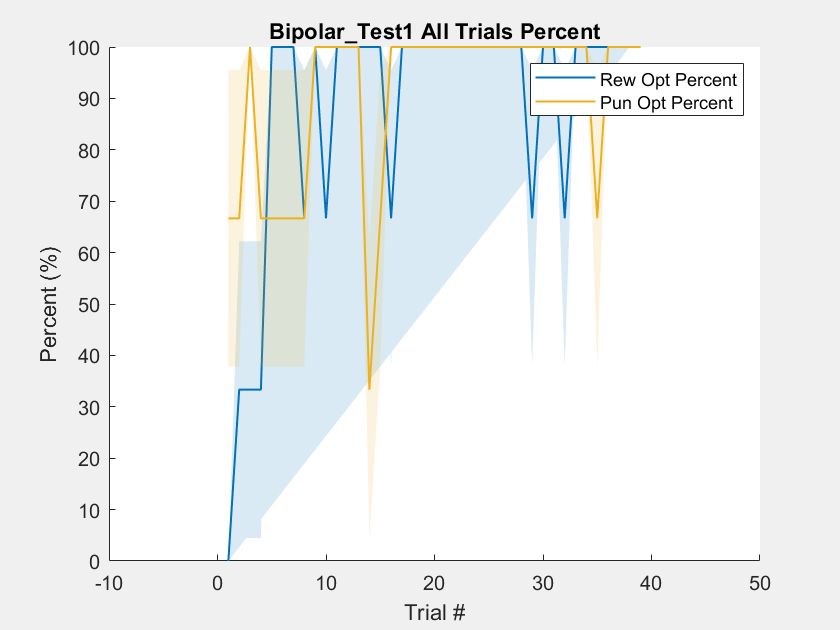

warning('off','MATLAB:handle_graphics:exceptions:SceneNode')

Deci.Run.Behavior = true;
Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.Extra = false ;

Deci.Plot.BslRef = 'Fdb Onset';
Deci.Plot.Lock = 'Fdb Onset';

Deci.Plot.GrandAverage = true;

Deci.Plot.Topo.do    =false;
Deci.Plot.Topo.Foi     = [4 7.5];                   % Frequency of Interest
Deci.Plot.Topo.Toi     = [.2 .5];                  % Time of Interest
Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.MTopo.do    =false;
Deci.Plot.MTopo.Foi     = [13 20];                   % Frequency of Interest
Deci.Plot.MTopo.Toi     = [0 .5];                   % Time of Interest
Deci.Plot.MTopo.ToiSegs = 4;
Deci.Plot.MTopo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Square.do  =true;
Deci.Plot.Square.Foi     = [3 inf];                 % Frequency of Interest
Deci.Plot.Square.Toi     = [-.5 1];                   % Time of Interest
Deci.Plot.Square.Channel = [{'Fz'}];                % Channel of Interest

Deci.Plot.Wire.do    =true;
Deci.Plot.Wire.XFreq = false;
Deci.Plot.Wire.Foi     = [20 35];           % Frequency of Interest
Deci.Plot.Wire.Toi     = [.2 .5];                   % Time of Interest
Deci.Plot.Wire.Channel = [{'Fz'}];              % Channel of Interest

Deci.Plot.Bar.do    =false;
Deci.Plot.Bar.Foi     = [20 35];              % Frequency of Interest
Deci.Plot.Bar.Toi     = [.25 5];                   % Time of Interest
Deci.Plot.Bar.Channel = [{'Fz'}];            % Channel of Interest
Deci.Plot.Bar.Type    = 'min';

Deci.Plot.Freq.Type    = 'TotalPower';
Deci.Plot.FreqYScale              ='log';

Deci.Plot.Bsl     = [-.1  0];

Deci.Plot.ColorMap = fliplr(brewermap(255,'spectral')')';
Deci.Plot.Size = [1000 580 915 760];


if Deci.Plot.Square.do
    Omnibus = false;


    if Omnibus == true
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Comp = 'Bsl';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.correctm = 'fdr';
        Deci.Plot.BslType ='db';
    else
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.correctm = 'no';
        Deci.Plot.BslType ='relchange';
    end
    Deci.Plot.Stat.FPlots =  false;
    %Deci.Plot.Roi = [-1 1];
elseif Deci.Plot.Topo.do || Deci.Plot.MTopo.do

    Perma = true;

    if Perma == true
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.correctm = 'no';
        Deci.Plot.Stat.FPlots =  false;
        %Deci.Plot.BslType = 'none';
    end

    %Deci.Plot.Roi = 'maxmin';
elseif Deci.Plot.Wire.do
    Deci.Plot.Stat.do = true;
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
    Deci.Plot.Stat.FPlots =  false;
    Deci.Plot.Stat.correctm = 'no';
    Deci.Plot.BslType = 'relchange';
    %Deci.Plot.Stat.Comp = 'Corr';
elseif Deci.Plot.Bar.do
    Deci.Plot.Stat.do = true;
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.FPlots =  false;
    Deci.Plot.BslType ='none';
    Deci.Plot.Roi = [0 .8];
end

Deci.Plot.Stat.twoway.do  = false;

Deci_Backend(Deci);